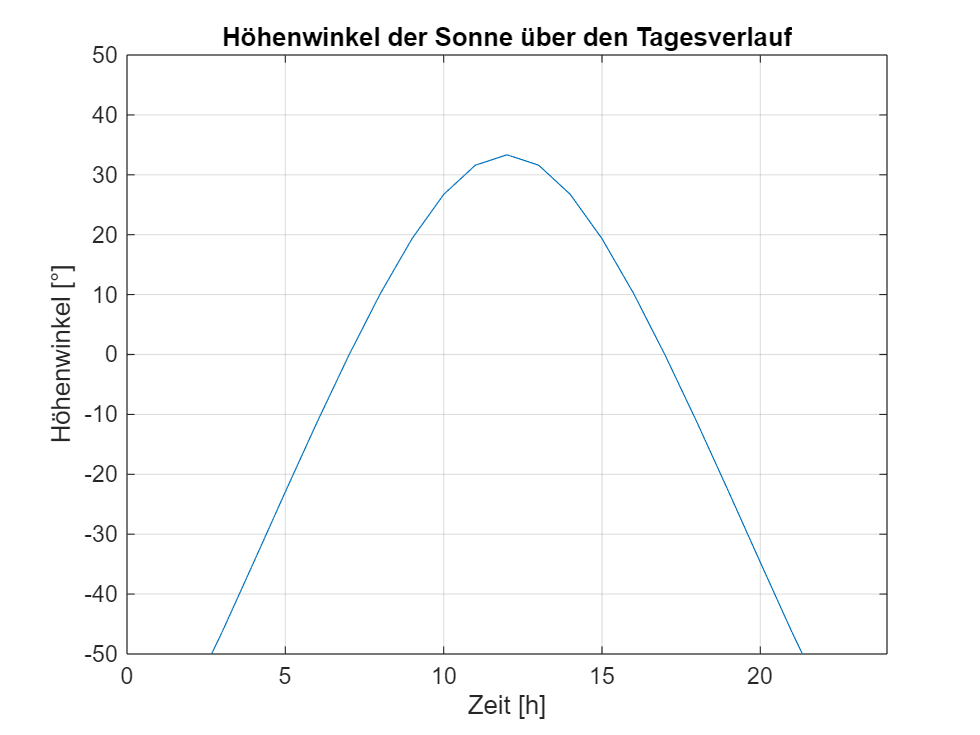

phi=38.1167; % geografische Breite von Palermo
t=0:1:24; % Tageszeiten
delta=Deklination(datetime('2025-01-28')); % Tag der Auswertung
H=Stundenwinkel(t);
a=Hoehenwinkel(phi,delta,t);
figure
plot(t,a)
xlabel("Zeit [h]");
ylabel("Höhenwinkel [°]");
title("Höhenwinkel der Sonne über den Tagesverlauf");
grid on;
ylim([-50 50]);
xlim([0 24]);

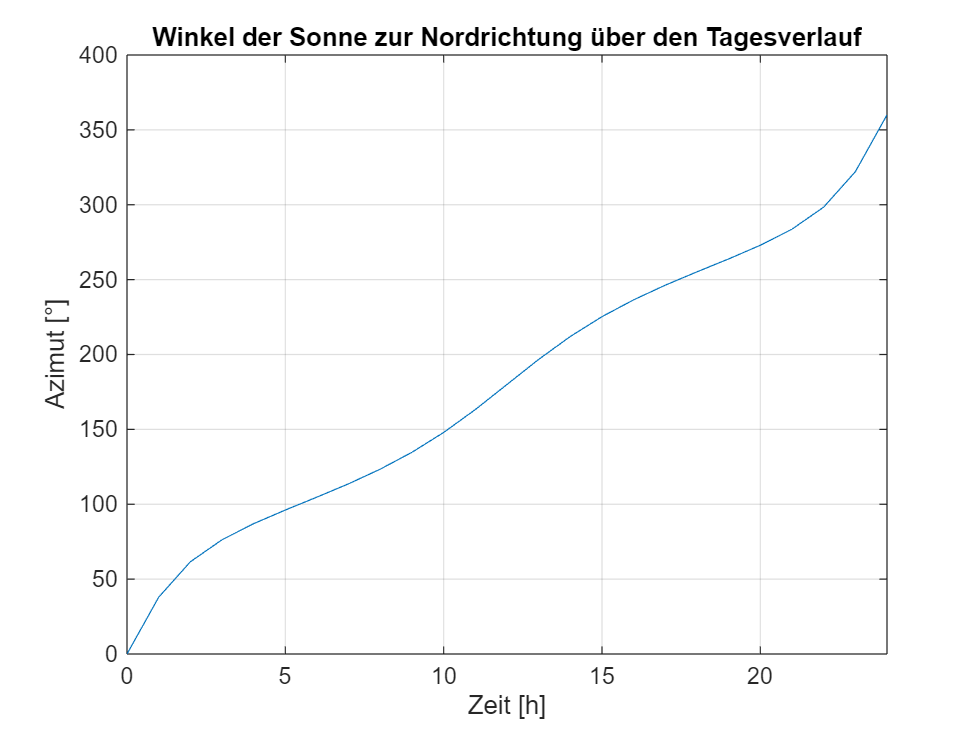


az=Azimut(delta,a,phi,t);
figure
plot(t,az)
xlabel("Zeit [h]");
ylabel("Azimut [°]");
title("Winkel der Sonne zur Nordrichtung über den Tagesverlauf");
%Nachmittags korrigiert
grid on;
xlim([0 24]);

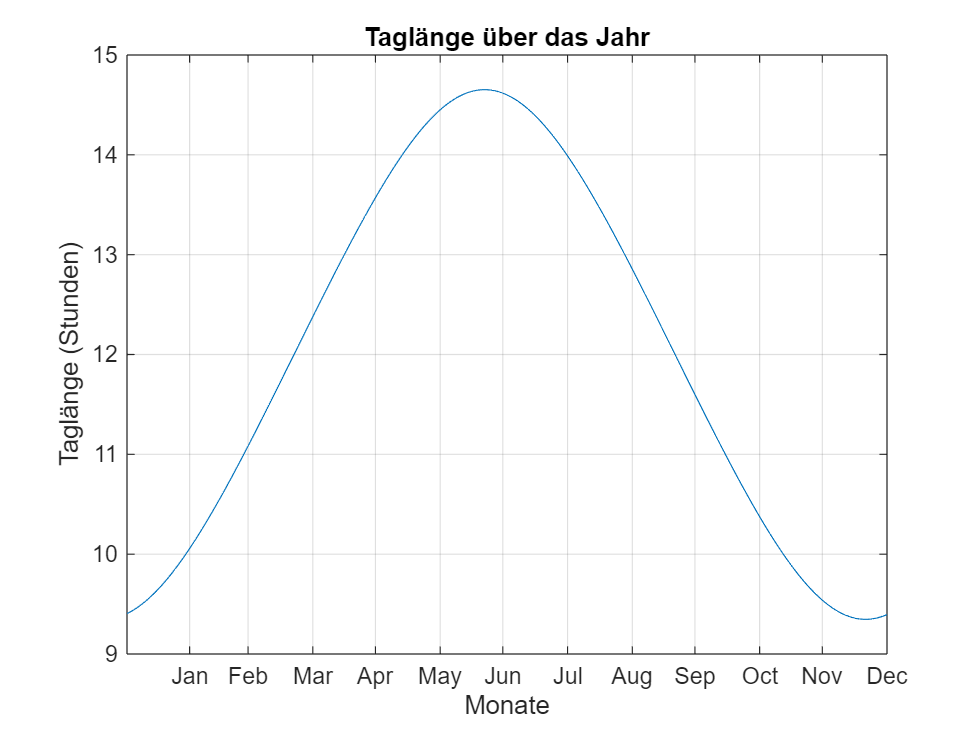

%azimut nach höhenwinkel<0 nicht mehr sichtbar

daylen=Taglaenge(phi);
figure
plot(1:365,daylen)
xlim([1,365]);
tage_pro_monat = [31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31];
tage_am_monat_ende = cumsum(tage_pro_monat);
xticks(tage_am_monat_ende);
months = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
xticklabels(months);
xlabel('Monate');
ylabel('Taglänge (Stunden)');
title('Taglänge über das Jahr');
grid on;

Die Energie die eine Horizontal ausgerichtete PV-Anlage jeweils zum 21. der Monate März, Juni, September und Dezember in Elektrizität umwandelt.

horizontal_ausgerichtet = Horizontal_ausgerichtete(phi)

Unrecognized function or variable 'Horizontal_ausgerichtete'.

## Fixierte optimale Ausrichtung

Welche Ausrichtung der Anlage wäre für den jeweils 21. der Monate März, Juni, September und Dezember optimal. Welche Ausrichtung wäre für das gesamte Jahr optimal? Um welchen Faktor verbessert sich die Ausbeute im Vergleich zur horizontalen Anlage.

date1=datetime("2025-03-21")

date1 = datetime
   21-Mar-2025


date2=datetime("2025-06-21")

date2 = datetime
   21-Jun-2025


date3=datetime("2025-09-21")

date3 = datetime
   21-Sep-2025


date4=datetime("2025-12-21")

date4 = datetime
   21-Dec-2025


[fix_opti_angles,fix_opti_energy] = Fixiert_optimal_ausgerichtet(phi, date1,date2,date3,date4);
fprintf("Für den %s ist die optimale Ausrichtung: Azimut= %.2f° Höhenwinkel= %.2f°",date1, fix_opti_angles(1,1), fix_opti_angles(1,2));

Für den 21-Mar-2025 ist die optimale Ausrichtung: Azimut= 115.85° Höhenwinkel= 61.83°

fprintf("Für den %s ist die optimale Ausrichtung: Azimut= %.2f° Höhenwinkel= %.2f°",date2, fix_opti_angles(2,1), fix_opti_angles(2,2));

Für den 21-Jun-2025 ist die optimale Ausrichtung: Azimut= 69.33° Höhenwinkel= 23.17°

fprintf("Für den %s ist die optimale Ausrichtung: Azimut= %.2f° Höhenwinkel= %.2f°",date3, fix_opti_angles(3,1), fix_opti_angles(3,2));

Für den 21-Sep-2025 ist die optimale Ausrichtung: Azimut= 115.60° Höhenwinkel= 61.61°

fprintf("Für den %s ist die optimale Ausrichtung: Azimut= %.2f° Höhenwinkel= %.2f°",date4, fix_opti_angles(4,1), fix_opti_angles(4,2));

Für den 21-Dec-2025 ist die optimale Ausrichtung: Azimut= 201.68° Höhenwinkel= 85.19°

fprintf("Über ein Jahr gesehen ergibt sich ein Mittelwert von Azimut= %.2f° Höhenwinkel= %.2f°", fix_opti_angles(5,1), fix_opti_angles(5,2));

Über ein Jahr gesehen ergibt sich ein Mittelwert von Azimut= 133.62° Höhenwinkel= 57.22°

fprintf("Die optimale Ausrichtung für maximalen Energieertrag über ein gesamtes Jahr leigt bei: Azimut= %.2f° Höhenwinkel= %.2f°", fix_opti_angles(6,1), fix_opti_angles(6,2));

Die optimale Ausrichtung für maximalen Energieertrag über ein gesamtes Jahr leigt bei: Azimut= 115.34° Höhenwinkel= 61.38°

fprintf("Für diese Ausrichtung liegt der Jahresenergieertrag bei %.2f kWh", fix_opti_energy/1000);

Für diese Ausrichtung liegt der Jahresenergieertrag bei 536.10 kWh